# Music Composition

[bass bFs]= audioread('bass.wav');
Tb = 1/bFs;
tb = 0: Tb : length(bass) * Tb - Tb;
[guitar gFs]= audioread('guitar.wav');
Tg = 1/gFs;
tg = 0: Tg : length(guitar) * Tg - Tg;
 [drums dFs]= audioread('drums.wav');
Td = 1/dFs;
td = 0: Td : length(drums) * Td - Td;
% subplot(311);
%plot(tb,bass);
% subplot(312);
%plot(tg,guitar);
% subplot(313);
%plot(td,drums);

% Time
size(bass)/bFs

ans =   105.3671    0.0000


size(guitar)/gFs

ans =   104.1516    0.0000


size(drums)/dFs

ans =   107.1650    0.0000


% Mixed Sound
basspart = bass(bFs * 10 : bFs * 30);
guitarpart = guitar(gFs * 10 : gFs * 30);
drumspart = drums(dFs * 10 : dFs * 30);

tt = 0:1/bFs:20

tt =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


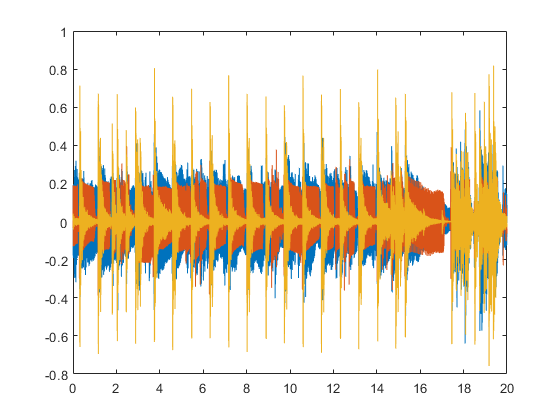


song = basspart + guitarpart + drumspart;
% sound(song, bFs) % WOW

% Mixed Plot
plot(tt,guitarpart)
hold on
    plot(tt,basspart)
    plot(tt,drumspart)
hold off

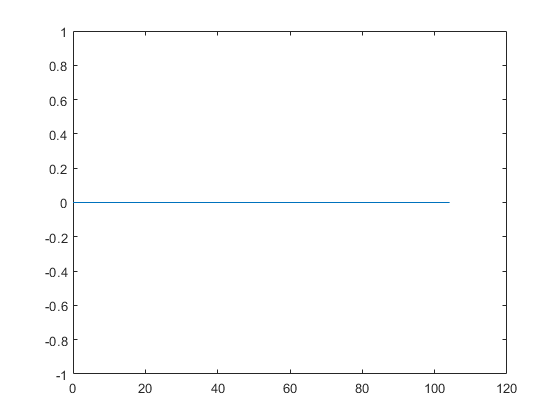

% Volume Up
L = length(guitar);
amp = linspace(0, 3, L);
newwave = [];
 for i = L:length(guitar)
a(i) = guitar(i).*amp(i);
end
sound(a, gFs)
plot(tg, a);

% Mono & Streo
[you yFs]= audioread('you.wav');
% sound(you,yFs);         % ฟังทั้งเพลง 2 ลำโพง
% sound(you(:,1),yFs);  % เสียงดนตรีลำโพงซ้าย (ในเครื่องคอมพิวเตอร์บางเครื่อง จะนำเอาสัญญาณเสียงโมโน ออกทั้ง 2 ลำโพง)
sound(you(:,2),yFs); % เสียงดนตรีลำโพงขวา

[road,fs]=audioread('road.wav'); 
%sound(road,fs);
left=road(:,1);
right=road(:,2);
sound(left-right,fs);